clear all
m = 1000;
b = 50;

% 크루즈시스템
s = tf('s');
P_cruise = 1/(m*s+b);
t_cruise = 0:0.1:30;
r_cruise = 10;

% 모터시스템
J = 3.2284E-6;
b = 3.5077E-6;
K = 0.0274;
L = 2.75E-6;
R = 4;
s = tf('s');
t_motor = 0:0.001:0.3;
r_motor = 1;
P_motor = K/(s*((J*s+b)*(L*s+R)+K^2));

% 시스템 설정
t_system = t_motor;
P_system = P_motor;
r_system = r_motor;

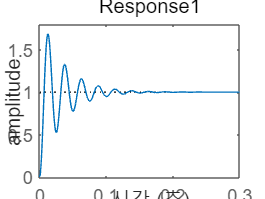

% P control 
Kp = 30; % rise time 개선
C = Kp;
sys_cl = feedback(C*P_system,1);
figure(1)
step(r_system*sys_cl,t_system)
ylabel('amplitude');
title('Response1');

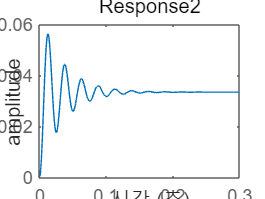


dist_cl = feedback(P_system,C);
figure(2)
step(dist_cl,t_system)
ylabel('amplitude');
title('Response2');

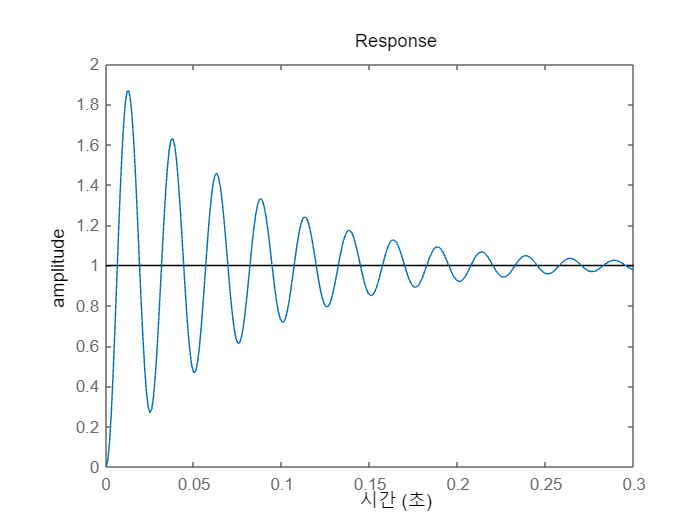

% PI control
Ki = 1000; % steady state error 개선
C = Kp + Ki/s;
sys_cl = feedback(C*P_system,1);
figure(3)
step(r_system*sys_cl,t_system)
ylabel('amplitude');
title('Response');

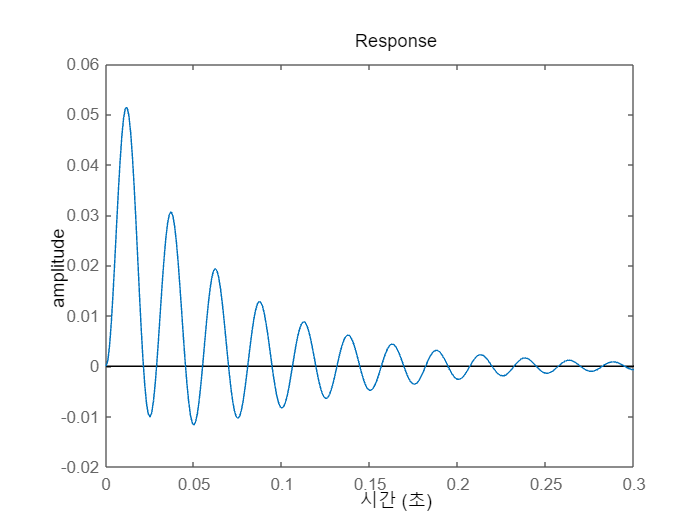


dist_cl = feedback(P_system,C);
figure(4)
step(dist_cl,t_system)
ylabel('amplitude');
title('Response');

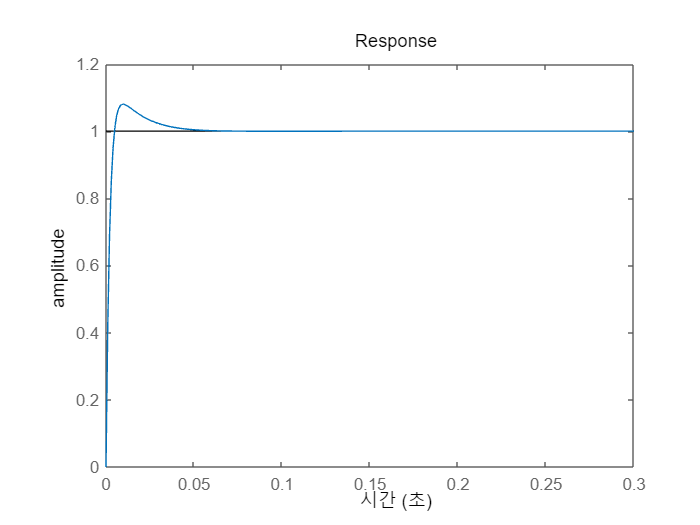

% PID control
Kd = 0.25; % trasient response를 부드럽게 개선
C = Kp + Ki/s + Kd*s;
sys_cl = feedback(C*P_system,1);
figure(5)
step(r_system*sys_cl,t_system)
ylabel('amplitude');
title('Response');

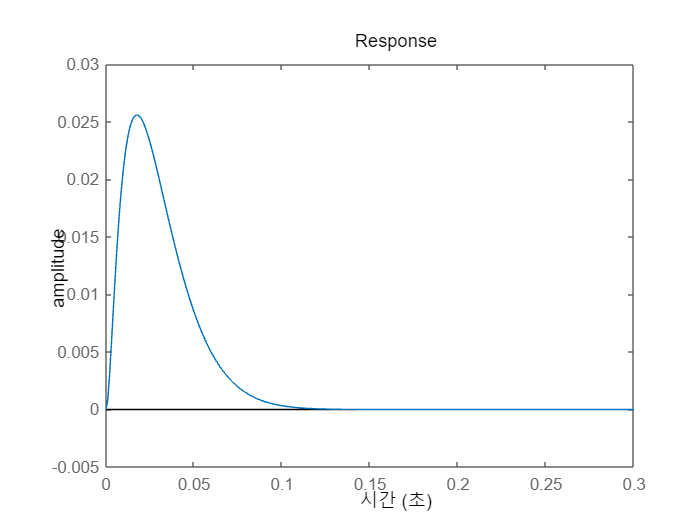


dist_cl = feedback(P_system,C);
figure(6)
step(dist_cl,t_system)
ylabel('amplitude');
title('Response');

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.0032
    TransientTime: 0.0316
     SettlingTime: 0.0316
      SettlingMin: 0.9142
      SettlingMax: 1.0802
        Overshoot: 8.0168
       Undershoot: 0
             Peak: 1.0802
         PeakTime: 0.0098


% pidTuner(P_system,'pid')